# Project Demo/Discussion

% Environment Setup
addpath(genpath('/Users/Anas/Documents/MATLAB/LibraryFiles_MATLAB/BrainNetViewer_20150414'))
addpath('/Users/Anas/Documents/MATLAB/LibraryFiles_MATLAB')
cd('/Users/Anas/Documents/MATLAB/Project_Demo')
load('fmri_data_allssubjects_AAL90.mat')

## **Time Series Data**

The data generally is of the form $D\in \Re^{N\ast T}$

    where N is the number of time series & T is the length of each time series

Consider the simple example as shown below (with $N = 5; T = 200$)

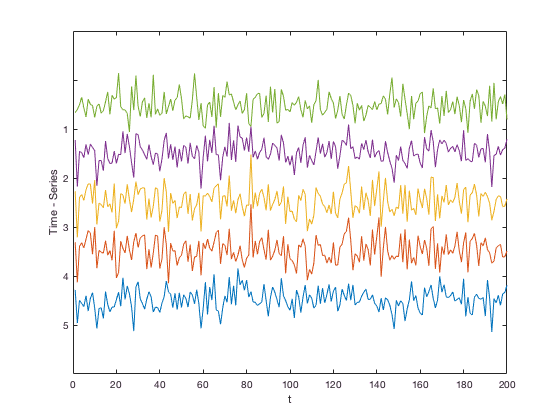

sigma  = 0.5;    % Scaling factor
X = sigma*randn(200, 1);
Y = sigma*randn(200, 1);

D(1,:) = X;
D(2,:) = Y;
D(3,:) = sqrt(0.2^2)*X+sqrt(1-0.2^2)*Y;
D(4,:) = sqrt(1-0.4^2)*X+sqrt(0.4^2)*Y;
D(5,:) = sigma*randn(200, 1);

plot((D + repmat(1:2:10,[200 1])')')
yticks([0:2:10])
yticklabels(fliplr([1:5]))
ylabel('Time - Series')
xlabel('t')

The simple mesure of a relationship between such time-series can be given using the correlation coefficient, which in fact is the most-widely used technique to study functional MRI data.

A connectivity matrix is a commonly used representation for such relationships. It represents the pariwise interactions between all time-series of a system. Hence for a system with N time-series a NxN connecitivity matrix is obtained. 

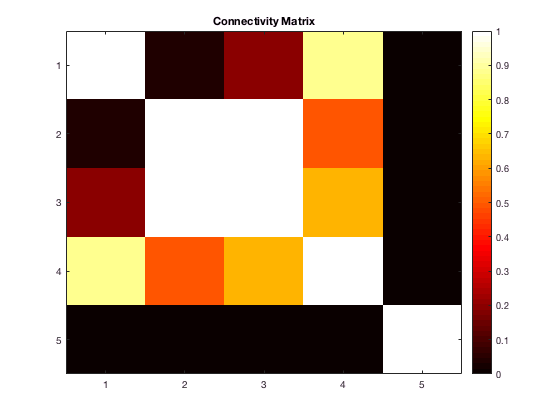

conn = corr(D');
imagesc(conn)
yticks([1:5])
xticks([1:5])
colorbar
colormap hot
caxis([0 1])
title('Connectivity Matrix')

Functional MRI data give the activities of the brain over a small period of time. It is a 4D representation ( a 3D brain recorded across time). A preprocessed dataset can be loaded into MATLAB as a 4D matrix (commonly of size $91x109x91xT$). 

From this we can either work with time-series from all voxels or focus ourselves one some specific regions that we are interested (for ex: regions from a standard atlas (AAL, DOS160 etc)) 

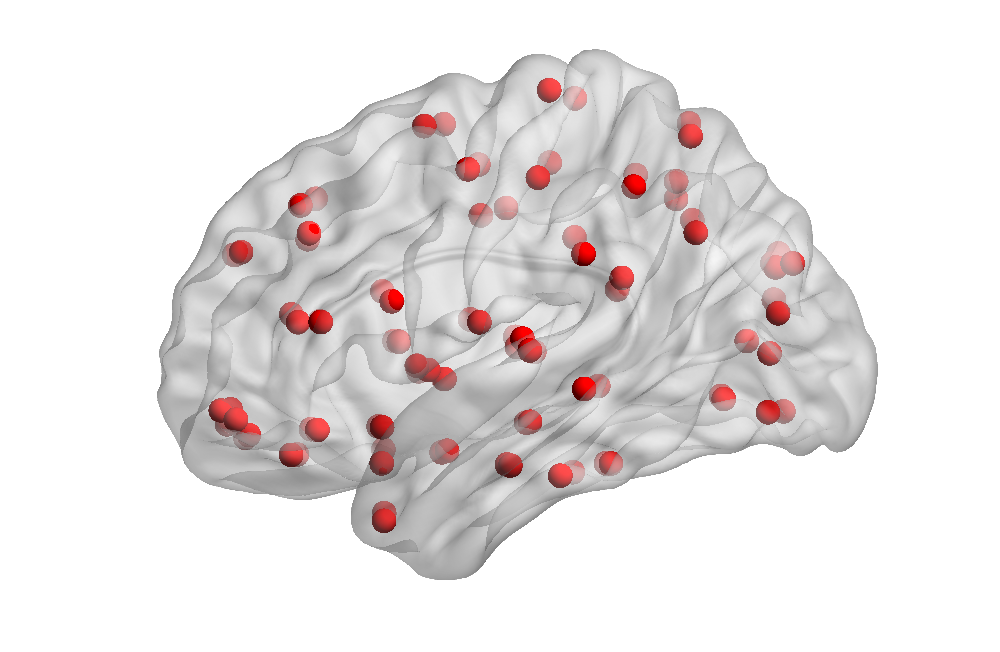

BrainNet_MapCfg('BrainMesh_ICBM152.nv','Node_AAL90.node','save_BN_optfile.mat');

Regional timeseries once extracted can give us a matrix $D$ of all the 90 time-series of the system. We can similarly compute a connectivity matrix.

fprintf(['Data Matrix Dimensions \n',num2str(size(data))])

Data Matrix Dimensions 
40   90  240

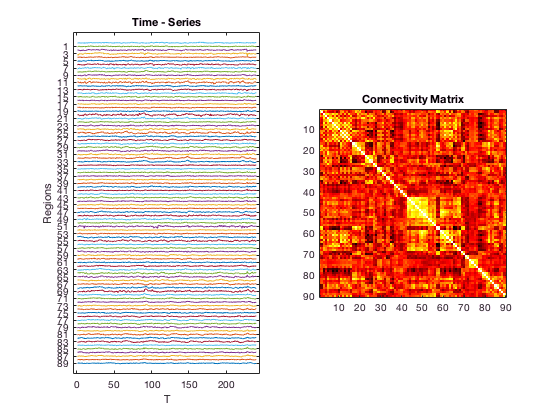

%there are 40 subjects in our cohort
subj = 1;
figure
subplot 121
plot((squeeze(data(subj,:,:)) + repmat(1:2:2*size(data,2),[size(data,3) 1])')')
xlim([-5 245])
ylim([-5 185])
yticks([1:4:180])
yticklabels(fliplr([1:2:90]))
title('Time - Series'); ylabel('Regions'); xlabel('T')
subplot 122
imagesc(corr(squeeze(data(subj,:,:))')); axis square
xticks(10:10:90); yticks(10:10:90); title('Connectivity Matrix'); colormap hot

## Improved Connectivity Characterization

To tackle the problem of connectivity between time-series we propose to use two theoretically distinct but applicable methods which have been explored in time-series literature. Within these theoretical frameworks, we develop two algorithms which have unique properties and with their intrinsic characteristics can be relevant to analysis of functional MRI data. The two fundamental theories can be briefly described as follows: 

- If the predictability of Y declines when X is removed from modelling the system of observations as compared to when X is included; X is said to *Granger cause* Y. 

- Theories on dynamic systems modelling state that if X causes another variable Y, information about X will be encoded within the past of Y.

**Mutual Connectivity Analysis with Radial Basis Function Neural Network**

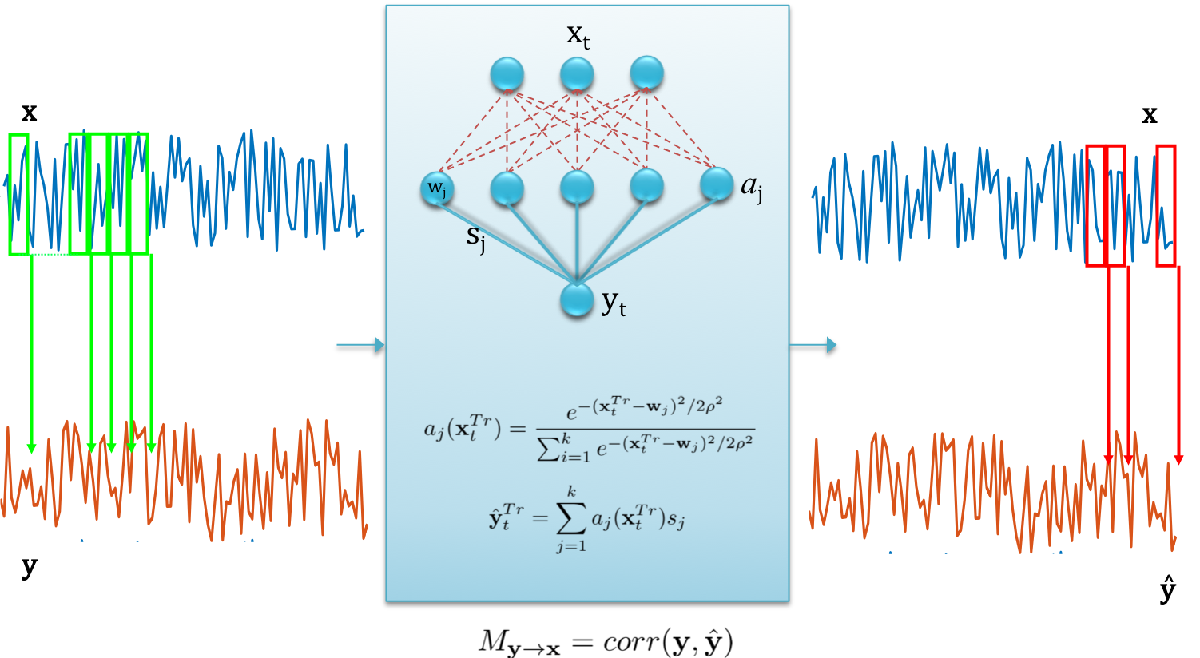 

Using these method we obtain connectivity matrices for each individual subject in our cohort. Futhermore, each method can capture something unique pertaining the connections in the brain, as seen below

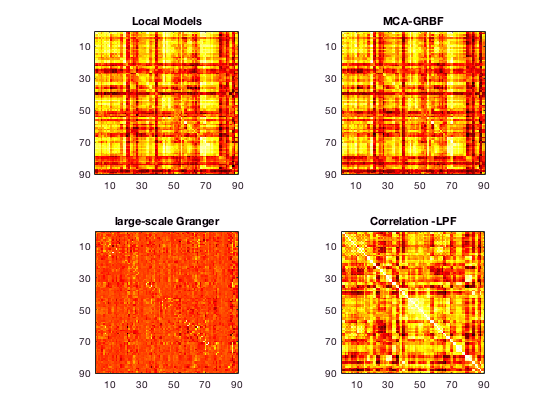

figure
subplot 221
imagesc(mean(Matrices_all(subj).LM,3))
axis square
xticks(10:20:90); yticks(10:20:90); title('Local Models')
subplot 222
imagesc(mean(Matrices_all(subj).GRBF,3))
axis square
xticks(10:20:90); yticks(10:20:90); title('MCA-GRBF')
subplot 223
imagesc(mean(Matrices_all(subj).lsGCI,3))
axis square
xticks(10:20:90); yticks(10:20:90); title('large-scale Granger')
subplot 224
imagesc(mean(Matrices_all(subj).Corr_filt_lpf,3))
axis square
xticks(10:20:90); yticks(10:20:90); title('Correlation -LPF')
colormap hot

## Graph Theoretic Analysis

The graph model (network affinity matrix) of the brain is an abstract structure used to represent pairwise relations between interregional ensembles of neuronal elements. This model can also be used to study particular effects or contrast of interest for e.g.: comparison between subject groups, modelling changes in response to functional paradigms or associations of regional interactions with clinical scores of interest. A mass-univariate comparison is the simplest route in these cases. However it presents with a requirement of multiple-comparisons corrections which substantially reduce the statistical power. For instance: a univariate hypothesis testing in network with a 90 nodes would require correction for $\left(\underset{2}{90} \right)$comparisons (for an undirected network) thereby markedly reducing the contrast to noise ratio and/or statistical power.

Researchers have reported *key organizational principles* of brain network topologies consistent between individuals as well as across species. A key property of the brain is its unique ability of ***optimize connectivity at the same time minimizing the cost of information flow*** across the network. Referred to as the, “small-world” characteristic, it can be accurately quantified by the use of graph theoretic approaches. Empirical studies of structural and functional brain networks in humans and other animals have reported small world properties of the brain. Deviation from crucial properties has been noted in various neurologic and psychiatric disorders.

These properties can be computed from weighted or binary versions of the affinity matrix and provide with simple summary measures of the full brain network.

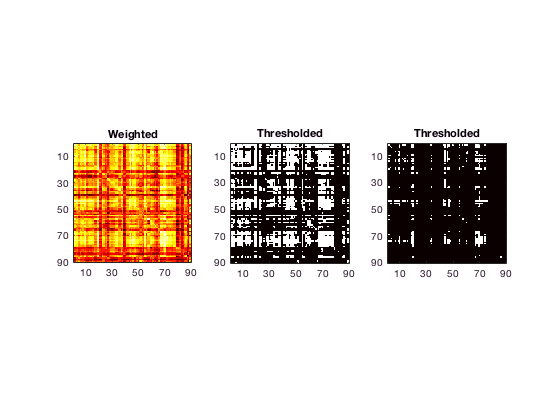

figure
subplot 131
imagesc(mean(Matrices_all(subj).LM,3))
axis square
xticks(10:20:90); yticks(10:20:90); title('Weighted')
subplot 132
imagesc(mean(Matrices_all(subj).LM,3)>0.5)
axis square
xticks(10:20:90); yticks(10:20:90); title('Thresholded')
subplot 133
imagesc(mean(Matrices_all(subj).LM,3)>0.7)
axis square
xticks(10:20:90); yticks(10:20:90); title('Thresholded')
colormap hot

%Graph Measures computation

mats = fieldnames(Matrices_all);

     FID      Assortativity       Degree        Degree_Var    Clustering_Coeff    Charpath    Efficiency    Modularity    Transitivity    SmallW
    ______    _____________    _____________    __________    ________________    ________    __________    __________    ____________    ______

    'FN01'    -0.02216         [3×90 double]       578         0.8861             1.5372      0.63125       0.075843      0.84791         1.0381
    'FN02'    -0.14604         [3×90 double]    547.83         0.8826             1.3708      0.59788        0.13265      0.83006         1.0989
    'FN03'     0.10916         [3×90 double]    319.07        0.79095          

clc
% for typ_num = 1:2
    typ_num = 1;
% pat_selected = [2,3,5,6,7,8,27,28,29,30,32,33];   %random choice
% pat_selected = [6,16,17,18,19,27,31,32,34,36];      % Age matched exact

Clinical and Demographic Characterisitcs
     FID       Cohort     Age      Gender      ATT_ZS      EXE_ZS      LEA_ZS      MEM_ZS      MOT_ZS      SPE_ZS     OVERALL_ZS
    ______    ________    ___    __________    _______    ________    ________    ________    ________    ________    __________

    'FN01'    ''HIV-''    39     ''Female''    0.11894      -1.222    -0.60183    -0.48558    -0.21717    -0.86046    -3.2682   
    'FN02'    ''HIV-''    44     ''Male''      -1.2009    -0.98138      1.8094       1.861     -0.3529    -0.07004     1.0652   
    'FN03'    ''HIV-''    52     ''Male''      0.28392      1.0041  

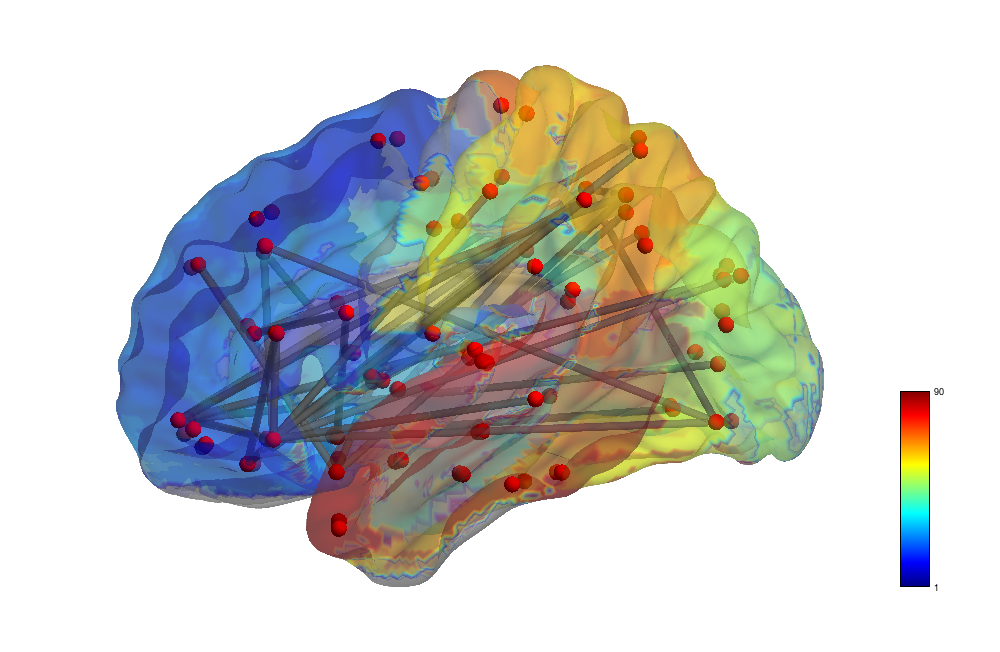

% controls = [6,16,13,18,19];
% patients = [27,31,29,34,36]; 
controls = [3,4,5,6,11,12,15,16,17,18];                  % with and without presence of HAND! 
patients = [21,22,23,24,29,34,35,36,39,40];                 % Approximately age matched

sub_selected = [controls,patients];
% sub_selected = 1:40;                              % All subs
mat = zeros(90,90,length(sub_selected),2);


seq = [1:4];

for ctr = 1:length(sub_selected)
    for num_seq = 1:length(seq)
       temp = mean(Matrices_all(sub_selected(ctr),seq(num_seq)).(mats{typ_num}),3);
%        temp = Matrices(sub_selected(ctr),seq(num_seq)).Corr_analysis_filt;
%        temp = GRBF_all_new(:,:,(pat_selected(ctr)-1)*4 + seq);
        mat(:,:,ctr,num_seq) = temp(1:90,1:90);
    end
end

R_hat_out = permute((squeeze(sum(mat.*(mat>0 & mat~=1),2))./89),[2,3,1]);
R_hat_in = permute((squeeze(sum(mat.*(mat>0 & mat~=1),1))./89),[2,3,1]);

%
Measures.R_hat_out = R_hat_out;
Measures.R_hat_in = R_hat_in;

q_level = [0.45:0.05:0.65];
for pat = 1:length(sub_selected)

    disp(['sub no : ', num2str(pat)])
for qctr = 1:length(q_level)
for seq = 1:4
    temp = mat(:,:,pat,seq);
    temp(1:length(temp)+1:end) = 1;
%     temp(temp<0) = 0;
    thr = quantile(temp(:),q_level(qctr));
%     thr = disc_lvl{seq}(pat,1);
    cd = sum(temp(:)>thr)/((90^2-90));
    for reg = 1:90
         Measures.Var_R_out(pat,seq,reg) = sum((R_hat_out(pat,seq,:) - R_hat_out(pat,seq,reg)).^2)/89;
         Measures.Var_R_in(pat,seq,reg) = sum((R_hat_in(pat,seq,:) - R_hat_in(pat,seq,reg)).^2)/89;
    end
    [d1,d2,d3] = degrees_dir(temp>thr);

    Measures.D_in(pat,seq,qctr,:) = d1;
    Measures.D_out(pat,seq,qctr,:) = d2;
    Measures.D_tot(pat,seq,qctr,:) = d3;
    
    Measures.Var_D_in(pat,seq,qctr) = var(d1);
    Measures.Var_D_out(pat,seq,qctr) = var(d2);
    Measures.Var_D_tot(pat,seq,qctr) = var(d3);
    
    Measures.Eff(pat,seq,qctr,:) = efficiency_bin(temp>thr,1);
    cc = clustering_coef_bd(temp>thr);
    Measures.Clu_Coef(pat,seq,qctr,:) =cc; 
    Measures.Ass(pat,seq,qctr) = assortativity_bin(temp>thr,0);
    [~,Measures.Modularity(pat,seq,qctr)] = modularity_und(temp>thr);
    [Measures.Global_Eff(pat,seq,qctr)] = efficiency_bin(temp>thr,0);
    Measures.Global_Clu_Coef(pat,seq,qctr,:) = mean(cc(d3>2));
    num_rand = 10;
    for nctr = 1:num_rand
        temp_random_net = randmio_und(temp>thr,5);
        [d] = degrees_und(temp_random_net);
        t_cc = clustering_coef_bu(temp_random_net);
        Clustering_Coeff_rand(nctr) = mean(t_cc(d>2));
        dist = distance_bin(temp_random_net);
        Charpath_rand(nctr) = charpath((dist));
    end
    
    Measures.SmallW(pat,seq,qctr) = ((mean(cc(d>2))/mean(Clustering_Coeff_rand))/(1/(efficiency_bin(temp>thr,0)*mean(Charpath_rand))));
    
    Measures.CC_rand(pat,seq,qctr) = mean(Clustering_Coeff_rand);
    Measures.CharPath_rand(pat,seq,qctr) = mean(Charpath_rand);
    
    
end
end
end

disp(meas_table(1:5,:))

**HIV Associated Neurocognitive Disorders**

The Human Immunodeficiency Virus is capable of crossing the blood brain barrier at an early stage during infection and causing damage to synaptodendritic connections resulting in neuronal dysfunction. Changes at the neuronal level can occur long before the symptoms manifest in an individual. With an increased life-expectancy owing to therapeutic advancements in treatment of HIV positive (HIV+) individuals, neurocognitive deficits affecting multiple domains eventually develop in over 50% HIV infected individuals. Thus, given the high likelihood of developing HAND in the long-term, there is an increasing demand for biomarkers that have the potential to improve early detection of injury to the central nervous system (CNS). 

*Can we use the summary statisitics from the graph analysis as biomarkers?*

disp('Clinical and Demographic Characterisitcs'); disp(HIVZscores1(1:5,:))

Marginal Association Analyses

The following multiple regression model was used for the marginal association analysis.


$${GM}_{ik} =Z_{il} \beta_{ik} +\text{ }\sum_{j=1}^{J} X_{ij} \gamma_{jk} +\text{ }\in_{ik}$$


where $Z_{il}$ can be 'Cohort' or 'HAND' status.

Regression *t*-test was performed for each $\beta_{ik}$ and correction for multiple testing was also performed using the Benjamini-Hochberg procedure to control False Discovery Rate.

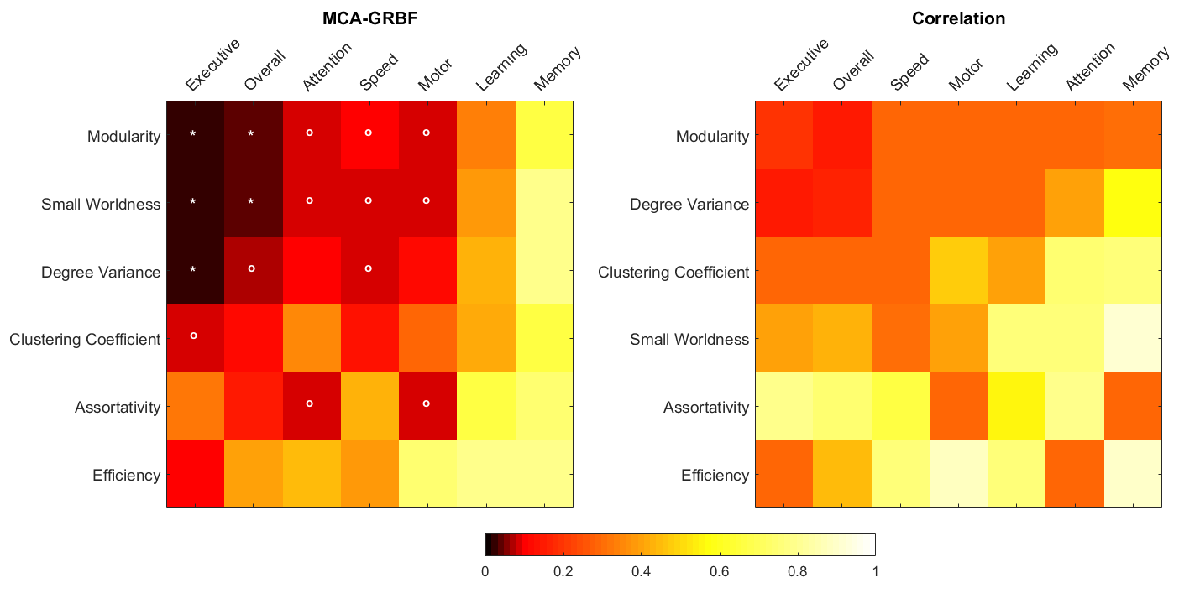

The alternative method suggested is the Network Based Statistic which can potentially serve to increase the statistical power when compared to conventional approaches such as false discovery rate (FDR) corrections. This technique focusses on finding small subnetworks which maybe different between two classes of subjects, hence a result such as the one below can be obtained.

BrainNet_MapCfg('BrainMesh_ICBM152.nv','Node_AAL90.node','LM_T31_adj.edge','aal.nii','save_BN_optfile2.mat');

As most of our newer methods are directed we can also explore the effect and existence of directed connections within the brain network. For this we study whether a directioncal preference say $A\longrightarrow B$ is consistently observed across all subjects or not. We performed this analysis on a smaller subnetwork of 32 region which are better understood during resting state and studied the directional specificity.